% Mohamed Ramzan / Start Date: 07/29/2024
% Detect Cat Breed in Real Time using camera

% Close all open figures
close all;

% Clear the workspace and command window
clear;
clc;

### Load the saved model

filename = 'trainedModelDog.mat';
load(filename, 'netTransfer');

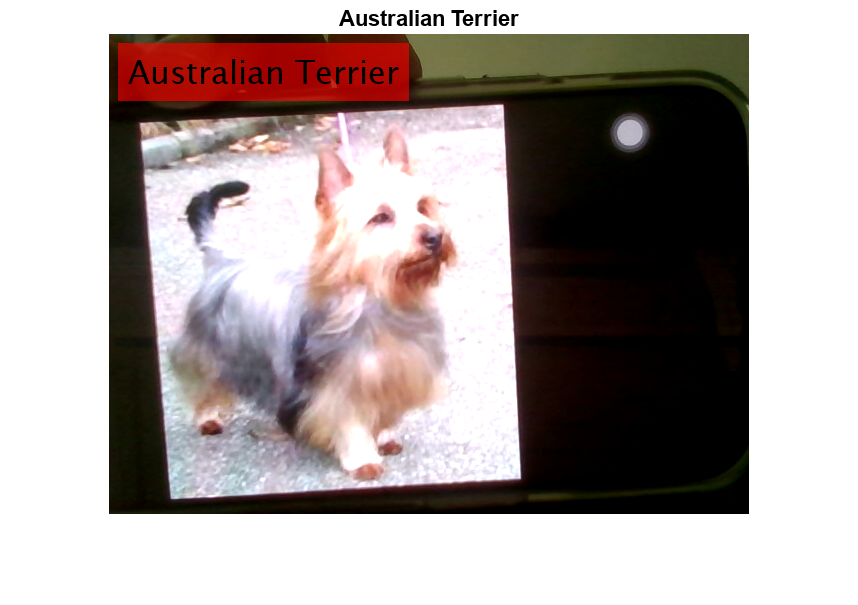

% Setup the webcam
cam = webcam;

% Define the input size of the network
inputSize =  [227 227 3];

% Create a figure window for displaying the results
figure;

while true
    % Capture a frame from the webcam
    img = snapshot(cam);
    
    % Resize the image to match the input size of the network
    imgResized = imresize(img, [inputSize(1) inputSize(2)]);
    
    % Classify the image using the loaded model
    label = classify(netTransfer, imgResized);
    
    % Convert label to string
    labelStr = char(label);
    
    % Insert the label text into the image
    position = [10 10]; % Position to insert text [x, y]
    imgWithLabel = insertText(img, position, labelStr, 'FontSize', 32, 'BoxColor', 'Red', 'BoxOpacity', 0.6);
    
    % Display the image with the classification result
    imshow(imgWithLabel);
    title(labelStr);
    
    % Pause for a short duration to allow the figure to update
    pause(0.1);
end


% Release the webcam when done
clear cam;

